% Andrew Hutsell
% MATH 515
% Guided Lab 1


% Exercise 1
approx = 1 + (24/60) + (51/(60^2)) + (10/(60^3))

approx = 1.4142

real_calc = sqrt(2);
abs_error = abs(approx-real_calc)

abs_error = 5.9941e-07

relative_error = abs(abs_error/real_calc)

relative_error = 4.2385e-07

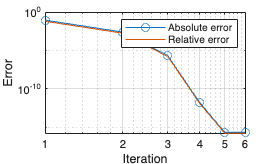

clear;clc;close all;
% Exercise 3
a = 2; 
y_n = 1; 
num_iterations = 6;

real_calc = sqrt(2);

abs_error = [];
relative_error = [];

for i = 1:num_iterations
    y_n_next = 0.5 * (y_n + (a / y_n));
    y_n = y_n_next;
    abs_error(i) = abs(y_n - real_calc);
    relative_error(i) = abs(abs_error(i) / real_calc);
end
n_array = 1:num_iterations;
loglog(n_array, abs_error, 'o-')
hold on
loglog(n_array, relative_error)
grid on
xlabel('Iteration')
ylabel('Error')
legend('Absolute error','Relative error')

The result of the calculation is extremely sensitive to the initial guess of y_n. As the value of y_n increases, the error for both the absolute and relative errors dramatically increase.

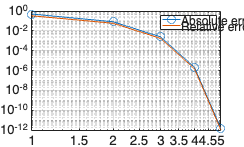

clear; clc; close all;
% Exercise 4
a = 2;
y_n = 1;
num_iterations = 6;

abs_error = zeros(1,num_iterations);
relative_error = zeros(1,num_iterations);

for i = 1:num_iterations
    y_n_past = y_n;
    y_n = 0.5 * (y_n + a/y_n);
    
    abs_error(i) = abs(y_n - y_n_past);
    relative_error(i) = abs_error(i)/abs(y_n);
end

n_array = 1:num_iterations;
loglog(n_array, abs_error, 'o-')
hold on
loglog(n_array, relative_error)
grid on
xlabel('Iteration')
ylabel('Error')
legend('Absolute error','Relative error')

% Exercise 5

y_n = sqrt(a)(1+delta_n)

y_{n+1} = 1/2(sqrt(a)(1+delta_n)+ a/(sqrt(a)(1+delta_n)))

y_{n+1} = 1/2 sqrt(a)((1+delta_n)+1/(1+delta_n))

(1+delta_n)+1/(1+delta_n)) = ((1+delta_n)^2+1)/(1+delta_n)

y_n+1 = 1/2 sqrt(a) (2+2 delta_n+delta_n^2)/(1+delta_n)

1/(1+delta_n) = 1 + O(delta_n)

delta_{n+1} = 1/2 delta_n^2+O(delta_n^3)

C = 1/2

delta_{n+1} = C delta_n^2 + O(delta_n^3)

% Exercise 6

% This is the first numerically computed absolute error from Exercise 3
e_0 = 0.085786437626905;
% Equation from Exercise 5
e_n_next = 0.5 * e_0^2

delta_n_next = 0.0037

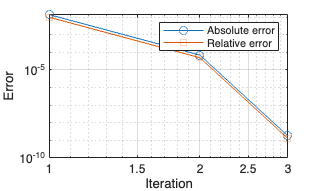

clear; clc; close all;
% Exercise 7

a = 2;
delta_n = 0.01;
y_n = sqrt(a) * (1 + delta_n);
num_iterations = 10;

abs_error = zeros(1,num_iterations);
relative_error = zeros(1,num_iterations);

for i = 1:num_iterations
    y_n_past = y_n;
    y_n = 0.5 * (y_n + a/y_n);
    
    abs_error(i) = abs(y_n - y_n_past);
    relative_error(i) = abs_error(i)/abs(y_n);
end

n_array = 1:num_iterations;
loglog(n_array, abs_error, 'o-')
hold on
loglog(n_array, relative_error, 's-')
grid on
xlabel('Iteration')
ylabel('Error')
legend('Absolute error','Relative error')

After 3 iterations, the computed error deviates significantly from the theoretical prediction.

clear; clc; close all;
% Exercise 9

a = 2;
initial_guess = [1.00, 1.25, 1.50, 1.75, 2.00];
num_iterations = 10;

for i = 1:length(initial_guess)
    y = initial_guess(i);
    fprintf('Initial guess = %.2f\n', y);
    
    for j = 1:num_iterations
        y = y + y^2 - a;
        fprintf('  iter %2d: y = %.6f\n', j, y);
    end
    fprintf('\n');
end

Initial guess y0 = 1.00


  iter  1: y = 0.000000
  iter  2: y = -2.000000
  iter  3: y = 0.000000
  iter  4: y = -2.000000
  iter  5: y = 0.000000
  iter  6: y = -2.000000
  iter  7: y = 0.000000
  iter  8: y = -2.000000
  iter  9: y = 0.000000
  iter 10: y = -2.000000


Initial guess y0 = 1.25


  iter  1: y = 0.812500
  iter  2: y = -0.527344
  iter  3: y = -2.249252
  iter  4: y = 0.809884
  iter  5: y = -0.534205
  iter  6: y = -2.248830
  iter  7: y = 0.808406
  iter  8: y = -0.538072
  iter  9: y = -2.248550
  iter 10: y = 0.807429


Initial guess y0 = 1.50


  iter  1: y = 1.750000
  iter  2: y = 2.812500
  iter  3: y = 8.722656
  iter  4: y = 82.807388
  iter  5: y = 6937.870946
  iter  6: y = 48140989.138608
  iter  7: y = 2317554883384593.500000
  iter  8: y = 5371060637499779110557422977024.000000
  iter  9: y = 28848292371699531221831972447673605943481989122971985097261056.000000
  iter 10: y = 832223972763057436562289452239314895188384119791587209226101161300388542326145681553038394964250847865706271652935800717312.000000


Initial guess y0 = 1.75


  iter  1: y = 2.812500
  iter  2: y = 8.722656
  iter  3: y = 82.807388
  iter  4: y = 6937.870946
  iter  5: y = 48140989.138608
  iter  6: y = 2317554883384593.500000
  iter  7: y = 5371060637499779110557422977024.000000
  iter  8: y = 28848292371699531221831972447673605943481989122971985097261056.000000
  iter  9: y = 832223972763057436562289452239314895188384119791587209226101161300388542326145681553038394964250847865706271652935800717312.000000
  iter 10: y = 692596740841526127755555968168567360280375826604935387467844104500250680215773542411485849591619318755806996066152798068972740549285443490436398145301173995772543286180278770572206867716660049107922470748264589523822026176519421268330803252690944.000000


Initial guess y0 = 2.00


  iter  1: y = 4.000000
  iter  2: y = 18.000000
  iter  3: y = 340.000000
  iter  4: y = 115938.000000
  iter  5: y = 13441735780.000000
  iter  6: y = 180680260792773935104.000000
  iter  7: y = 32645356640144803492991947409349492604928.000000
  iter  8: y = 1065719310162246417945036458679168545084579591127956116634459528088402288558735360.000000
  iter  9: y = 1135757648052694298741671448771337178171434619119732866101594631822743735182222977273784437599533964244686044805206332361131548624796836367740963990343503526756352.000000
  iter 10: y = Inf


clear; clc; close all;
% Exercise 10
a = 2;
N = 20;

% Method 1
x = 1.5;
err_1 = [];
x_real = sqrt(a);
for n = 1:N
    x = (1 / 4) * (3 * x + (2 / x));
    err_1(n) = abs(x - x_real);
end

err_1

err_1 =     0.0441    0.0224    0.0113    0.0057    0.0028    0.0014    0.0007    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000




% Method 2
z = 1.5;
err_2 = [];
z_real = sqrt(a);
for n = 1:N
    z = (1 / 8) * (3 * z + (12 / z) - (4 / (z^3)));
    err_2(n) = abs(z - z_real);
end

err_2

err_2 = 1.0e-03 *

    0.1383    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000




% Method 3

% Bisection Method
bound1 = 1.4;
bound2 = 1.5;
w = (bound1 + bound2) / 2;

w_real = sqrt(a);
err_3 = [];
for n = 1:N
    if (w^2 < a)
        bound1 = w; % Update lower bound
    else
        bound2 = w; % Update upper bound
    end
    w = (bound1 + bound2) / 2; % Recalculate midpoint
    err_3(n) = abs(w-w_real);
end

err_3

err_3 =     0.0108    0.0017    0.0045    0.0014    0.0002    0.0006    0.0002    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
